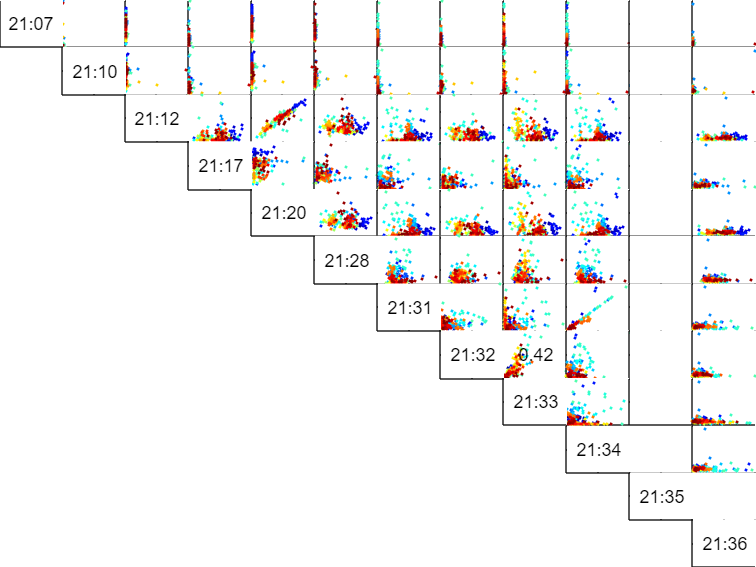

Features = DFD_FeatureTable_TimeDomain_Standard;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
r2ReducedThreshold = 0.9;
selectedFeature = 4; % Kurtosis
saveFigures = true;
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames);        

disp(num2str(R2, '%.2f  '));

0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN  0.00
0.00  0.00  0.00  0.01  0.00  0.00  0.00  0.00  0.00  0.00   NaN  0.30
0.00  0.00  0.00  0.01  0.88  0.01  0.00  0.06  0.09  0.00   NaN  0.01
0.00  0.00  0.00  0.00  0.00  0.01  0.11  0.10  0.00  0.10   NaN  0.02
0.00  0.00  0.00  0.00  0.00  0.02  0.01  0.09  0.09  0.00   NaN  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.02  0.03  0.00   NaN  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.08  0.01  0.93   NaN  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.42  0.07   NaN  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01   NaN  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


## Combination 1

selectedSignal = 9;
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectSignals(...
    selectedSignal, selectedFeature, featureArray_Standard, R2, upperR2, lowerR2, r2ReducedThreshold, true);

     8     9
     8     9


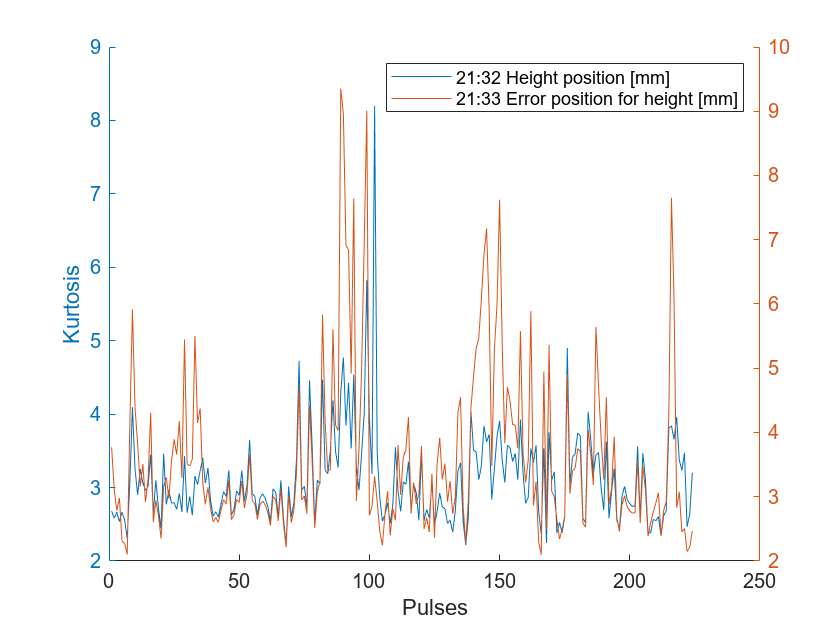

figure(); hold on;
FeatureNames(selectedFeature);%title(FeatureNames(selectedFeature));
xlabel("Pulses");
ylabel(FeatureNames_Combined(selectedFeature));
secondaryAxisArrayIndex = [2 3];
for i = 1:numOfSelectedSignals
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
    else
        yyaxis left;
    end
    plot(selectedSignalData{i});
    leg{i} = char(sensorNames(selectedSignalArray(i)));
end
legend(leg);

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
        + "Signal" + selectedSignal;
    %print(filename,'-depsc','-tiff')
    export_fig(filename, '-depsc');
end

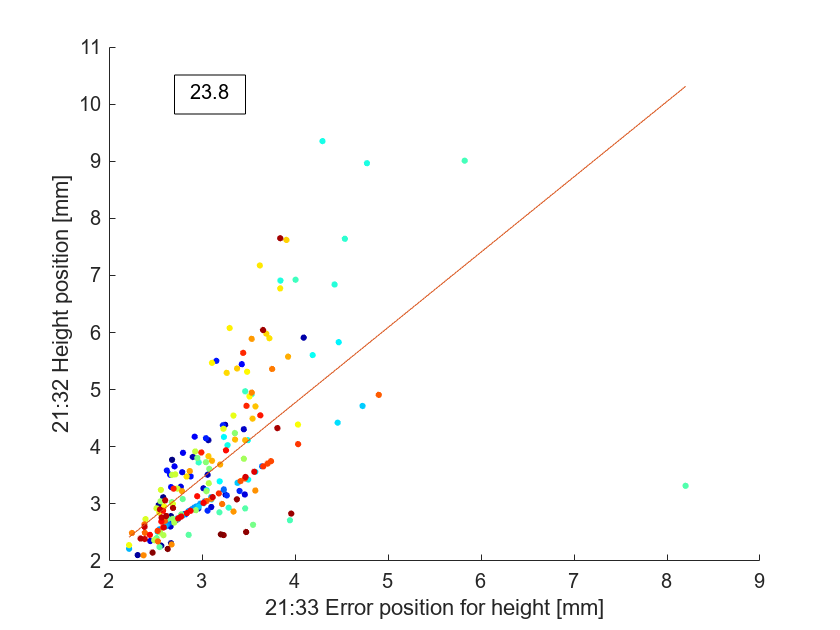

selectedSignalIdx = find(selectedSignalArray == selectedSignal);
linearModelNum = 1;
for index = 1 : numOfSelectedSignals
    if selectedSignalArray(index) ~= selectedSignal
        fnPlotModel(selectedSignalData{selectedSignalIdx}, ...
            selectedSignalData{index}, ...
            FeatureNames_Combined(selectedFeature), ...
            sensorNames(selectedSignalArray(index)), ...
            sensorNames(selectedSignal));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
                + "Signal" + selectedSignal ...
                + "_Linear" + linearModelNum;
            %export_fig(filename, '-eps', '-depsc');
            print(filename, '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

multivariateModelNum = 1;
if numOfSelectedSignals > 2
    for index1 = 1 : numOfSelectedSignals
        for index2 = index1+1 : numOfSelectedSignals
            if selectedSignalArray(index1) ~= selectedSignal && selectedSignalArray(index2) ~= selectedSignal 
                Y_est = fnPlotModel3D( ...
                    selectedSignalData{selectedSignalIdx}, ...
                    selectedSignalData{index1}, ...
                    selectedSignalData{index2}, ...
                    FeatureNames(selectedFeature), ...
                    sensorNames(selectedSignalArray(selectedSignalIdx)), ...
                    sensorNames(selectedSignalArray(index1)), ...
                    sensorNames(selectedSignalArray(index2)));

                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
                        + "Signal" + selectedSignal ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end